# Assignment 4: Euler case studies in 1D

## Sod Shock Tube

During the validation of compressible solvers, the shock tube Riemann problem, also known as the Sod problem, is widely used since the solution can be obtained analytically. A shock tube consists of a pipe with circular or rectangular cross-section which is filled with a gas. The tube is split into two parts by a diaphragm being positioned in the middle of it. Numerically, the diaphragm is modeled as a discontinuity in initial fluid conditions (density, pressure and temperature) across this surface.

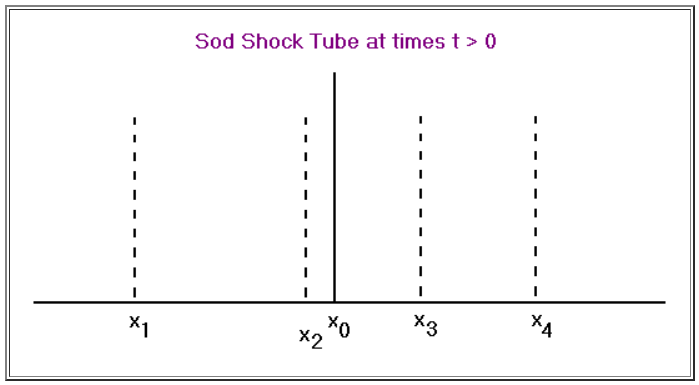

x0: Location of the initial membrane

x1: Head of the rarefaction wave that is moving to the left

x2: Tail of the rarefaction wave

x3: Location of the contact discontinuity that separates the "left" fluid from the "right"

x4: Location of the shock front that is moving to the right.

The initial conditions are very simple for this problem: a contact discontinuity separating gas with different pressure and density, and zero velocity everywhere. In the standard case the density and pressure on the left are unity, The density on the right side of the diaphragm is 0.125 and the pressure is 0.1. The ratio of specific heats is 1.4.

By solving the Euler equations, we can provide a time evolution for three characteristics after removing the membrane, describing the propagation speed of the rarefaction wave, the contact discontinuity (surface that separates zones of different density and temperature) and the shock discontinuity. Some important parameters are:

pPost: Pressure between x2 and x4 (post shock fluid).

vPost: Speed at which the "post shock" fluid is moving towards the right.

vShock: Speed of the shock front.

𝜌Middle: Density between x2 and x3.

𝜌Post: Density between x3 and x4.

Notice that to obtain the shock jump condition we need to figure out the values of vPost and pPost. The value of P that satisfies:

is the desired value of pPost. Then,

.

In the **Auxiliar functions definition **section we can find a short function that solves the sod shock tube problem. We can select the number of points to evaluate the physical properties and a particular time instant:

nNodes = 1000;
t      = 0.2;
solSST = solveSodShockTube(nNodes,t);

Output argument "pPost" (and possibly others) not assigned a value in the execution with
"Assignment4_Report>solveSodPostPressureEquation" function.

Error in Assignment4_Report>solveSodShockTube (line 21)
pPost     = solveSodPostPressureEquation();

## Questions

**1. Note that the code is incompleted: the function *****solveSodPostPressureEquation *****does not compute the value of pPost. Complete the function to make the code operative again.**

**2. Using 1000 nodes plot the spatial evolution of density, pressure, velocity and the energy for t=0.2. Comment the obtained results.**

**3. Using 1000 nodes plot the transient evolution of the head and tail of the rarefaction wave. Comment the obtained results and compute the transient evolution of the rarefaction wave tail speed.**

**4. Using 1000 nodes plot the transient evolution of the shock front. Comment the obtained results.**

## Supersonic Flow Past a Wedge

## **Auxiliar functions definition**

Sod Shock Tube solver:

function sol = solveSodShockTube(nNodes,t)

% Constants
gamma = 1.4;
mu    = sqrt( (gamma-1)/(gamma+1) );

% Initial conditions
x0       = 0;
rhoLeft  = 1;
PLeft    = 1;
uLeft    = 0;
rhoRight = 0.125;
PRight   = 0.1;
uRight   = 0;
cLeft    = power( (gamma*PLeft/rhoLeft),0.5);

% Post shock results
pPost     = solveSodPostPressureEquation();
vPost     = 2*(sqrt(gamma)/(gamma - 1))*(1 - power(pPost, (gamma - 1)/(2*gamma)));
rhoPost   = rhoRight*(( (pPost/PRight) + mu^2 )/(1 + mu*mu*(pPost/PRight)));
vShock    = vPost*((rhoPost/rhoRight)/( (rhoPost/rhoRight) - 1));
rhoMiddle = (rhoLeft)*power((pPost/PLeft),1/gamma);

%Key Positions
x1 = x0 - cLeft*t;
x3 = x0 + vPost*t;
x4 = x0 + vShock*t;

%determining x2
c2 = cLeft - ((gamma - 1)/2)*vPost;
x2 = x0 + (vPost - c2)*t;

%boundaries
xMin = -0.5;
xMax = 0.5;

x       = linspace(xMin,xMax,nNodes);
sol.x   = x';
sol.rho = zeros(nNodes,1);   %density
sol.P   = zeros(nNodes,1); %pressure
sol.u   = zeros(nNodes,1); %velocity
sol.e   = zeros(nNodes,1); %internal energy

for index = 1:nNodes
    if sol.x(index) < x1
        %Solution b4 x1
        sol.rho(index) = rhoLeft;
        sol.P(index)   = PLeft;
        sol.u(index)   = uLeft;
    elseif (x1 <= sol.x(index) && sol.x(index) <= x2)
        %Solution b/w x1 and x2
        c = mu*mu*((x0 - sol.x(index))/t) + (1 - mu*mu)*cLeft;
        sol.rho(index) = rhoLeft*power((c/cLeft),2/(gamma - 1));
        sol.P(index)   = PLeft*power((sol.rho(index)/rhoLeft),gamma);
        sol.u(index)   = (1 - mu*mu)*( (-(x0-sol.x(index))/t) + cLeft);
    elseif (x2 <= sol.x(index) && sol.x(index) <= x3)
        %Solution b/w x2 and x3
        sol.rho(index) = rhoMiddle;
        sol.P(index)   = pPost;
        sol.u(index)   = vPost;
    elseif (x3 <= sol.x(index) && sol.x(index) <= x4)
        %Solution b/w x3 and x4
        sol.rho(index) = rhoPost;
        sol.P(index)   = pPost;
        sol.u(index)   = vPost;
    elseif x4 < sol.x(index)
        %Solution after x4
        sol.rho(index) = rhoRight;
        sol.P(index)   = PRight;
        sol.u(index)   = uRight;
    end
    sol.e(index) = sol.P(index)/((gamma - 1)*sol.rho(index));
end
end

Function to compute the pressure of the "post shock" fluid:

function pPost = solveSodPostPressureEquation()
% Complete...

end